# Regresión: Conceptos Básicos

**Trabajo previo sugerido**

[MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted): un tutorial introductorio gratuito de dos horas para aprender lo esencial de MATLAB. 

Puedes ejecutar este script en un modo solo con controles usando el botón **Hide code ** , o ver el código usando el botón **Output inline**    en la pestaña **View **de la barra de herramientas de MATLAB.

## ¿Qué es la regresión?  

La regresión se refiere a técnicas para estimar la relación entre una variable dependiente y una o más variables independientes. En otras palabras, es una manera de modelar una variable objetivo (dependiente) en función de otras variables (independientes). La regresión se utiliza ampliamente para:

- Explicar o cuantificar la relación entre variables  

- Predecir o realizar pronósticos a partir de datos

### Regresión Lineal Simple

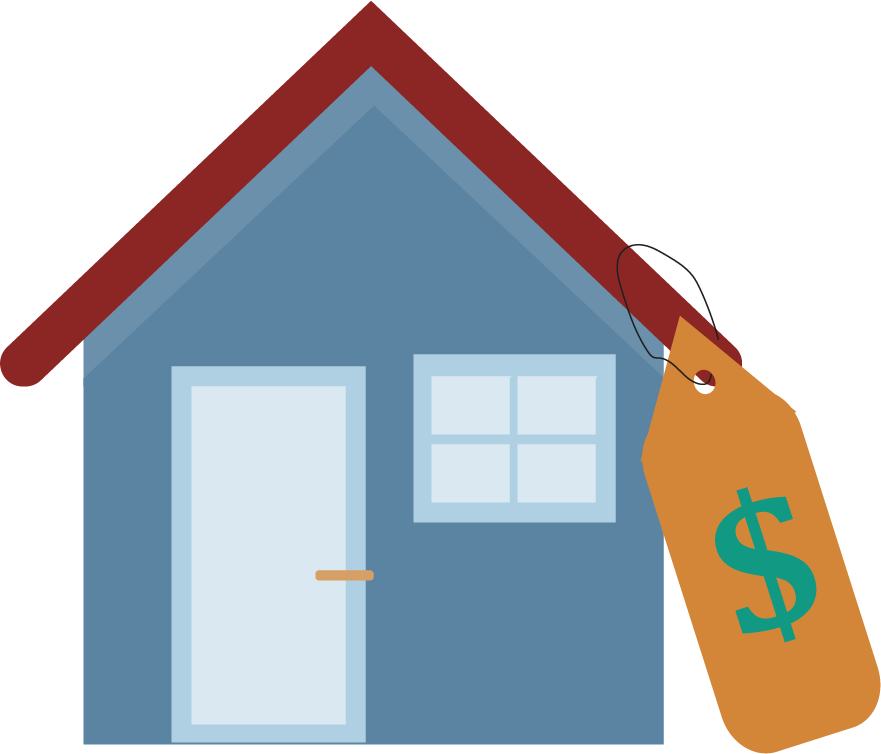 Supón que quieres estimar el valor actual de tu casa en el mercado. Basándote en tu experiencia, crees que los metros cuadrados de una vivienda pueden ser un buen indicador de su valor. Por ello, buscas los listados recientes en el vecindario para verificar y modelar la relación entre el precio de la propiedad y su superficie (área).

Tarea: Haz clic en el botón de abajo para cargar y graficar los precios de las casas y los metros cuadrados en un diagrama de dispersión.

***Tarea:**** Haz clic en el botón de abajo para cargar y graficar los precios de las casas y los metros cuadrados en un diagrama de dispersión.*

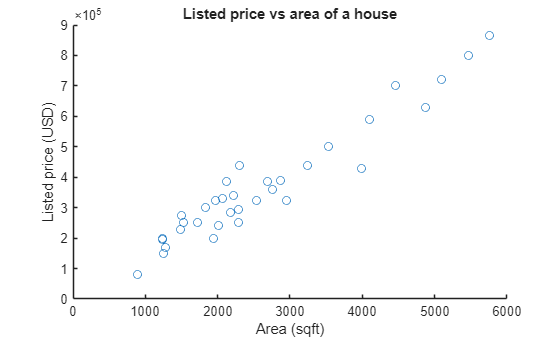

 
load LinearData.mat x y                     % Cargar datos desde un archivo MAT

figure;
scatter(x,y)                                % Graficar los puntos de datos
xlabel("Área (pies cuadrados)")             % Etiquetar el eje X
ylabel("Precio listado (USD)")              % Etiquetar el eje Y
title("Precio listado vs área de una casa") % Agregar un título

 **Reflexión**

- ¿Ves alguna tendencia o patrón en los datos?

Aquí tienes una variable dependiente (precio) y una variable independiente (área) que parecen estar correlacionadas linealmente. Este es un problema de regresión lineal simple, que utiliza una línea recta para modelar la relación entre una variable dependiente ($y$) y una variable independiente ($x$):

                            
$$y\;=a_0 +a_1 x$$


***Tarea****: Haz clic en el botón ****Run ****para graficar una línea con la pendiente *$a_1$ *y la intersección *$a_0$*.*

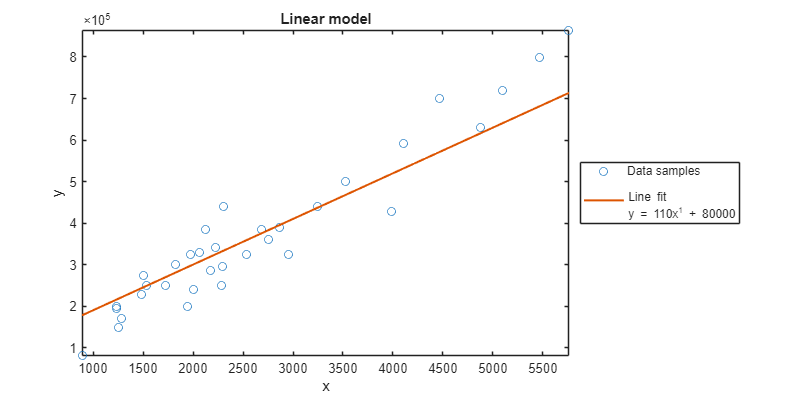

load LinearData.mat x y 
a1 =110;            % Set value for coefficient a1
a0 =80000;         % Set value for coefficient a0
 
figure("Position",[0 0 800 400]);          % Set up a figure for the plot
PlotFit(x,y,[a1 a0],0);                    % Call the helper function to plot the polynomial fit and the data samples

  **Prueba**

- *Utiliza los deslizadores para establecer las variables de pendiente (*$a_1$*) y ordenada al origen ((*$a_0$*) y generar diferentes líneas para modelar la relación.*

- *Ajusta los valores de a1 y a0 para encontrar una línea recta aproximada que modele o se ajuste a los datos.*

**Reflexiona ** 

- ¿Qué tan fácil fue encontrar los mejores coeficientes?  

- ¿Cómo determinaste que esta línea es un buen ajuste para los datos?  

- ¿Ahora puedes estimar el precio de una casa con un área de 3800 pies cuadrados?  

- Según este modelo, ¿puedes predecir el valor de una casa con un área de 10,000 pies cuadrados? Si la respuesta es sí, ¿qué supuestos estás haciendo?

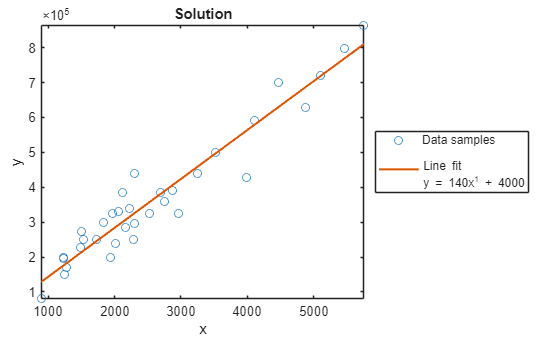

f = openfig('linearSoln.fig'); f2 = figure; set(f.Children(2),'Parent',f2)

#### Regresión por Mínimos Cuadrados Ordinarios

Tu objetivo con la regresión es encontrar el mejor modelo que describa la variable dependiente como una función de la/s variable/s independiente/s. Una forma de cuantificar qué tan bien se ajusta tu modelo es calculando la suma de los errores al cuadrado (SSE, por sus siglas en inglés) entre los valores reales y los valores predichos de la variable dependiente..

                            
$$\textrm{SSE}=\;\sum_{i=1}^n {\left(y_i -\hat{y_i } \;\right)}^2$$


                            $y_i \;$            es el valor real de la variable dependiente correspondiente a la muestra de datos número $i^{\textrm{th}}$de un total de $n$ muestras

                            ${\hat{y} }_i \;$            es el valor predicho correspondiente a la muestra $i^{\textrm{th}}$de datos, de un total de n muestras

***Tarea: ***Haz clic en el botón ***Visualize errors***  para ver las barras de error y mostrar la suma de los errores al cuadrado.

load LinearData.mat x y                     % Load data from a MAT file
a1 = 140;                                   % Set value for coefficient a1
a0 = 4000;                                  % Set value for coefficient a0
 
figure("Position",[0 0 800 400]);
PlotFit(x,y,[a1 a0],1);                     % Visualize the errors

Sustituyendo el modelo de línea recta para los valores predichos, el objetivo de la regresión lineal simple ahora puede formularse como el siguiente problema de minimización:

                        
$$\min_{a_0 ,a_1 } \sum_{i=1}^n {\left(y_i -\left(a_0 +a_1 x_i \right)\right)}^2$$


Puedes resolver esto analíticamente para $a_1$ y $a_0$ y obtener:

                        $a_1$=$\frac{\sum_{i=1}^n \left(x_i -\bar{x} \right)\left(y_i -\bar{y} \right)}{\sum_{i=1}^n {\left(x_i -\bar{x} \right)}^2 }$                           

                        
$$a_0 =\bar{y} -a_1 \bar{x}$$


donde

                        $\bar{x}$ es el promedio de todos los $x_i$

                        $\bar{y}$ es el promedio de todos los $y_i$

                        $i$ indica las muestras individuales de datos de un total de $n$ muestras

**Ejercicio:** Verifica si tu selección manual de `a1` y `a0` coincide con los valores que obtienes de esta solución analítica. Puedes hacerlo programáticamente (en modo **Code Inline**) o a mano.

xbar = mean(x)
ybar = mean(y)

% Calcula los valores de a1 y a0 usando las ecuaciones derivadas y las variables x, y, xbar y ybar.
% INGRESA EL CÓDIGO ABAJO



### Regresión Lineal Múltiple

  Considera otra variable, además de los pies cuadrados o área de una casa, que pueda ayudar a informar los precios de la casa. Por ejemplo, puedes incluir el número de electrodomésticos adicionales y otras características especiales en la casa en tu análisis.

***T******area:**** Haz clic en el botón de abajo para cargar y graficar los precios de las casas, el área y el número de características especiales en un diagrama de dispersión.*

 
load MultivariateData.mat x1 x2 y                   % Load the data
figure;
scatter3(x1,x2,y,"o")                               % Plot the data points
xlabel("Additional house features (#)")             % Label the axes         
ylabel("Area (sqft)")
zlabel("Listed price (USD)")                    
title("House prices")                               % Add a title
view([-150 20])                                     % Adjust the line or sight

**Reflexiona**

- ¿Ves alguna tendencia o patrón en los datos?

Aquí tienes una variable dependiente y dos independientes. Puedes realizar una *regresión multivariable*. Si el modelo es lineal en sus coeficientes, como la ecuación de un plano, también se llama *regresión lineal múltiple*.

                            
$$y=ax_1 +bx_2 +c{\mathrm{x}}_3 +\ldotp \ldotp \ldotp$$


Esta vez, *estandaricemos* las variables para facilitar la búsqueda de los coeficientes del modelo; es decir, centra y escala cada variable para que tenga una media de 0 y una desviación estándar de 1.

***T******area:**** Usa la función* [`n``ormalize`](https://www.mathworks.com/help/matlab/ref/double.normalize.html) *para estandarizar las variables* `x2`* y* `y`* en los campos de edición dados a continuación.*

load MultivariateData.mat x1 x2 y                     % Load the data
x1 =normalize(x1);                             % Standardize the data to have a mean of 0 and a standard deviation of 1
x2 =x2;
y = y;

***Tarea****: Haz clic en el botón ****Run**** para generar un plano con los coeficientes definidos abajo.*

a =-0.2;
b =0.2;
c =0.008;
 
figure("Position",[0 0 800 400]);                     % Set up a figure for the plot
PlotMultiFit(x1,x2,y,[a b c]);                        % Call the helper function to plot the polynomial fit and the data samples

  ***P******rueba***

- *Usa los deslizadores para fijar los valores de los coeficientes *$a$, $b$, and $c$* y generar diferentes planos para modelar la relación lineal.*

- *Fija los valores de* `a`*,* `b`* y* `c`* para encontrar el mejor plano que describa los datos. Esto puede ser muy desafiante. Para ayudar en el proceso, usa las herramientas de la gráfica como* ***Rotate *** * y* ***Pan***  *que aparecen en la esquina superior izquierda de la ventana de la figura.*

 **Reflect**

- ¿Qué tan fácil o difícil fue encontrar los mejores coeficientes para describir el modelo?

- ¿Cómo determinaste que los coeficientes que elegiste generaron un buen ajuste?

disp("Use the drop-down to reveal a likely solution")

## Funciones auxiliares

Function to plot a one-variable linear regression of any degree.

function yhat = PlotFit(x,y,A,ErrorFlag)

% Prepare data and compute the model predictions
powers = length(A)-1:-1:0;
X = x'.^powers;
yhat = A*X';

% Plot
plot(x,y,"o");
DispLine = sprintf("\nLine fit \n" + "y = " + join(A + ["x^{"+string(powers(1:end-1))+"}",""] ," + "),"Interpreter","tex");
xlim([min(x)-0.5,max(x)+0.5]);
ylim([min(y)-0.5,max(y)+0.5]);
hold on
fplot(@(x)A*(x'.^powers)',"LineWidth",1.5);
legend("Data samples",DispLine,"Location","eastoutside")
hold off
xlabel("x")
ylabel("y")
title("Linear model")

if ErrorFlag
    hold on
    DispSSE = sprintf("\nErrors \nSSE = %12g",sum(yhat-y).^2);
    errorbar(x,y,min(yhat-y,0),max(yhat-y,0),".","vertical","DisplayName",DispSSE,SeriesIndex = 3);
    hold off
end

end

Function to plot a plane fit based on its coefficients.

function yhat = PlotMultiFit(x1,x2,y,coeffs)

% Split the coefficients into individual variables and estimate y.
[a,b,c] = deal(coeffs(1),coeffs(2),coeffs(3));
yhat = a.*x1 + b.*x2 + c;

% Plot
scatter3(x1,x2,y);
xlim([min(x1)-0.1,max(x1)+0.1]);
ylim([min(x2)-0.1,max(x2)+0.1]);
zlim([min(y)-0.1,max(y)+0.1]);
[X1,X2] = meshgrid(xlim,ylim);
hold on
surf(X1,X2,a.*X1 + b.*X2 + c,"FaceAlpha", 0.4,"FaceColor",[1 0.5 0.5],"EdgeColor","none");
hold off
% Annotate
title("Multiple linear model")
DispPlane = sprintf("\nPlane fit"+"\ny = " + a + "x_{1} + " + b + "x_{2} + " + c);
legend("Data samples",DispPlane,"Location","eastoutside");
view([-150 20])
xlabel('x_{1}'), ylabel('x_{2}'), zlabel("y")

end

Function to plot a nonlinear fit based on model function (mdl) and two parameters (a,b).

function PlotNlinFit(x,yRel,a,b,mdl)
plot(x,yRel,"o");                                       % Plot the data samples
hold on
fplot(@(x)mdl(x,a,b))                                   % Plot the fitted model
hold off
title("Nonlinear model")                                % Add title
xlabel("Salinity in the root zone (dS/m)")              % Label the X axis
ylabel("Relative crop yield")                           % Label the Y axis
str = compose("$y = \\frac {1}{1+(\\frac {x}{%2g})^{%2g}}$",a,b);
legend("Data samples",newline + "S-curve fit","Interpreter","latex")
text(10.5,0.7,str,"Interpreter","latex","FontSize",20);
end

Function to perform and visualize gradient descent using mean-squared error cost for linear regression.

function [a1,a0,mse] = GradientDescent(x,y,steps,LearningRate)

% Prepare variables for visualizing the surface plot of cost function
[M,B] = meshgrid(-10:0.1:10,-10:0.1:10);
cost = arrayfun(@(m,b)CostFunc(m,b,x,y),M,B);

% Initialize loop
a1 = 7;                       % initial slope value
a0 = 7;                       % initial intercept value
n = length(x);                % total number of data points
mse = CostFunc(a1,a0,x,y);    % compute initial MSE
r = logspace(-0.5,0,steps);  % red color intensities for the plots

% Plot three different visualizations
T = tiledlayout(2,2,"TileSpacing","compact","Padding","compact");

% Plot 1: surface
nexttile(T,1)
surf(M,B,cost,"EdgeColor","none")
hold on
plot3(a1,a0,mse,"*",SeriesIndex = 2);
hold off
colormap(parula(30))
view([-16 33])
xlabel("a1"), ylabel("a0"), zlabel("Cost (MSE)")

% Plot 2: contour
nexttile(T,2)
contour(M,B,cost,30,"LineWidth",2)
hold on
plot(a1,a0,"*","MarkerSize",8,SeriesIndex = 2)
hold off
xlabel("a1"), ylabel("a0")

% Plot 3: line fit
title(T,"Gradient descent")
nexttile(T,[1,2])
plot(x,y,"o")
hold on
FitLine = plot(xlim,a1.*xlim+a0,"-","LineWidth",1.5,SeriesIndex = 2);
hold off
ylim([-10,10]), xlabel("x"), ylabel("y")


for step=1:steps

    % Compute gradient descent
    pause(0.02)
    yhat = a1*x + a0;
    diff = yhat - y;
    da1 = LearningRate * sum(diff .* x) * 2 / n;
    da0 = LearningRate * sum(diff) * 2 / n;
    a1 = a1 - da1;
    a0 = a0 - da0;
    mse = CostFunc(a1,a0,x,y);

    % Plot new iteration data over the existing plots
    nexttile(T,1)
    hold on
    plot3(a1,a0,mse,"*",SeriesIndex = 2);
    hold off

    nexttile(T,2)
    hold on
    plot(a1,a0,"*","MarkerSize",8,SeriesIndex = 2)
    hold off

    nexttile(T,3)
    FitLine.YData = a1*xlim+a0;
    title("a1 = "+a1 + ", a0 = "+a0, "MSE = "+mse)

end
end

Function to compute mean-squared error for a line fit.

function mse = CostFunc(m,b,x,y)
yhat = m*x+b;
mse = sum((yhat-y).^2)/length(x);
end

Generate multiple predictor variables for hourly load.

function [HourlyLoad,dates,predictors] = GetMultiPredictors(nyiso)
tt = retime(nyiso,"hourly","mean");
pred = tt.HUDVL;
N = [7 24 168];
predictors = [[nan(N(1),1); pred(1:end-N(1))],[nan(N(2),1); pred(1:end-N(2))],[nan(N(3),1); pred(1:end-N(3))]];
HourlyLoad = tt.HUDVL;
dates = tt.Date;
end
